# Bermudan Put - Naive Quadrature 

clear; clc; 

function price = bermudan_quad_naive(S0,K,r,q,sigma,T,n_steps,m_grid)
    h   = T / n_steps;                % adaptive daily step
    s0  = log(S0);
    smin = s0 - 10*sigma*sqrt(T);
    smax = s0 + 10*sigma*sqrt(T);
    s    = linspace(smin,smax,m_grid)'; 
    S    = exp(s);
    mid  = ceil(m_grid/2);
    ds   = s(2) - s(1);

    % Conditional density matrix F(s_j | s_i)
    mu_shift = (r - q - 0.5*sigma^2)*h;
    sig_h    = sigma*sqrt(h);
    F = zeros(m_grid);
    for i = 1:m_grid
        mu_i = s(i) + mu_shift;
        z = (s' - mu_i)/sig_h;
        F(i,:) = (1/(sig_h*sqrt(2*pi))) * exp(-0.5*z.^2);
    end

    % Simpson weights
    w = ones(m_grid,1);
    w(2:2:end-1)=4; w(3:2:end-2)=2;
    w = w*(ds/3);

    % Terminal Payoff
    v_next = max(K - S, 0);
    disc   = exp(-r*h);

    % Backward Recursion
    for t = 1:n_steps
        cont = disc * (F * (v_next .* w));
        v = max(K - S, cont);
        v_next = v;
    end

    price = v_next(mid);
end

tic;
S0=50; K=50; r=0.05; q=0.02; sigma=0.30;
T=60/365; n_steps=60; m_grid=401;
price = bermudan_quad_naive(S0,K,r,q,sigma,T,n_steps,m_grid);
fprintf('Naive Bermudan (no smoothing): %.6f\n',price);

Naive Bermudan (no smoothing): 2.308281


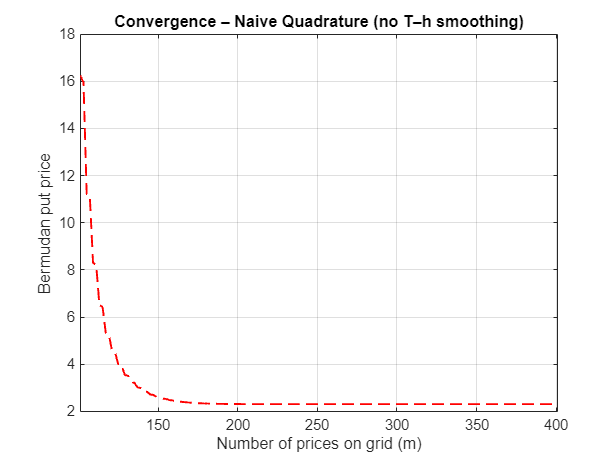

Elapsed time is 0.983498 seconds.


Smooth Bermudan (T–h smoothing): 2.308280


Elapsed time is 0.031368 seconds.


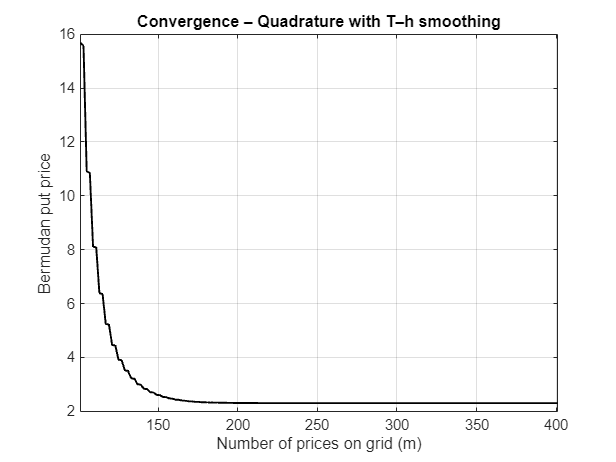

Elapsed time is 0.861441 seconds.


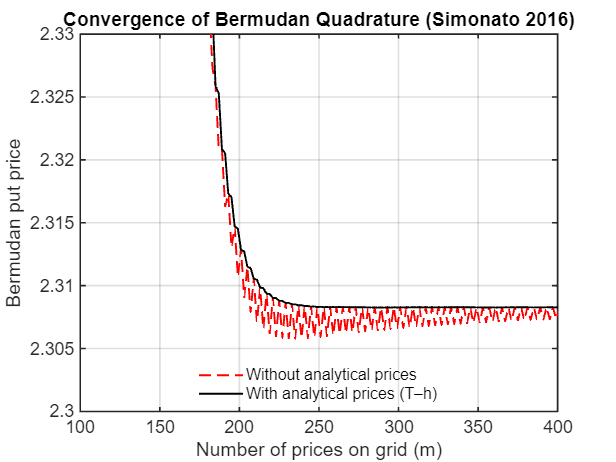

Elapsed time is 1.598569 seconds.


toc;

% Convergence sweep 
m_list = 101:2:m_grid;
prices = nan(size(m_list));
for k = 1:numel(m_list)
    prices(k) = bermudan_quad_naive(S0,K,r,q,sigma,T,n_steps,m_list(k));
end

% Plot
figure; hold on; box on;
plot(m_list, prices,'k-','LineWidth',1.3);
xlabel('Number of prices on grid (m)');
ylabel('Bermudan put price');
title('Convergence – Naive Quadrature (no T–h smoothing)');
grid on; xlim([min(m_list) max(m_list)]);